# Memory Data Analysis

Author: Prutha Patel

#### Background

Board games and puzzles play an important role during childhood in dictating executive functioning of working memory, integration of information and planning action. Playing board games and solving puzzles during childhood provides cognitive, behavioral and social training. 

Previously I focused my research question if childhood puzzle and board game play associated with better word recall performance in adulthood under shallow processing and deep processing conditions. 

This project extends the research question to understand differenct childhood experiences association with word recall performance. 

#### Research Question

This project extends into further question to undererstand:

- Which childhood experience best predict recall performances?

- Can machine learning models predict memory recall scores?

#### Load and Cleaning Data

% Load dataset
memorydata = readtable ('FinalDataset.csv')

memorydata = 220×69 table
      SID       AdministrationMethod      ParticipantLocation         DOB        Age    Gender    RaceEthnicity    PrimaryLanguage    IsSecondLanguage    SecondLanguage    SecondLangAgeofExposure    SecondLangTypeofExposure    PrimaryCareGivers    HighestParentEducation    FirstParentEducation    SecondParentEducation    HouseholdIncome    NumofSiblings    BirthOrder                                     FirstWordTask                                     ConfidenceWT1                                              SecondWordTask                                              ConfidenceWT2

summary(memorydata)


memorydata: 220×69 table

Variables:

    SID: cell array of character vectors
    AdministrationMethod: cell array of character vectors
    ParticipantLocation: cell array of character vectors
    DOB: datetime
    Age: double
    Gender: cell array of character vectors
    RaceEthnicity: cell array of character vectors
    PrimaryLanguage: cell array of character vectors
    IsSecondLanguage: double
    SecondLanguage: cell array of character vectors
    SecondLangAgeofExposure: double
    SecondLangTypeofExposure: cell array of character vectors
    PrimaryCareGivers: double
    HighestParentEducation: double
    FirstParentEducation: double
    SecondParentEducation: double
    HouseholdIn


% Creating a new dataset with only revelent coloumns
data = memorydata (:, {'SID','Age','Gender','FreqPuzzles','FreqVideoGames','FreqSocialMedia', ...
    'FreqReadForFun','FreqArtWorkFun','FreqExercise','FreqMusicalInstrument','FreqListentoMusic', ...
    'FreqListentoMusicwithHomework','FreqSpendTimeOutdoor','FreqFastFood','FreqSnackFood', ...
    'CorrectRecalledNumShallow','CorrectRecalledNumDeep','CorrectRecalledNumAvg'})

data = 220×18 table
      SID       Age    Gender    FreqPuzzles    FreqVideoGames    FreqSocialMedia    FreqReadForFun    FreqArtWorkFun    FreqExercise    FreqMusicalInstrument    FreqListentoMusic    FreqListentoMusicwithHomework    FreqSpendTimeOutdoor    FreqFastFood    FreqSnackFood    CorrectRecalledNumShallow    CorrectRecalledNumDeep    CorrectRecalledNumAvg
    ________    ___    ______    ___________    ______________    _______________    ______________    ______________    ____________    _____________________

summary(data)


data: 220×18 table

Variables:

    SID: cell array of character vectors
    Age: double
    Gender: cell array of character vectors
    FreqPuzzles: double
    FreqVideoGames: double
    FreqSocialMedia: double
    FreqReadForFun: double
    FreqArtWorkFun: double
    FreqExercise: double
    FreqMusicalInstrument: double
    FreqListentoMusic: double
    FreqListentoMusicwithHomework: double
    FreqSpendTimeOutdoor: double
    FreqFastFood: double
    FreqSnackFood: double
    CorrectRecalledNumShallow: double
    CorrectRecalledNumDeep: double
    CorrectRecalledNumAvg: double

Statistics for applicable variables:

                                     NumM


% Changing Gender column to categorical value
data.Gender = categorical(data.Gender)

data = 220×18 table
      SID       Age    Gender    FreqPuzzles    FreqVideoGames    FreqSocialMedia    FreqReadForFun    FreqArtWorkFun    FreqExercise    FreqMusicalInstrument    FreqListentoMusic    FreqListentoMusicwithHomework    FreqSpendTimeOutdoor    FreqFastFood    FreqSnackFood    CorrectRecalledNumShallow    CorrectRecalledNumDeep    CorrectRecalledNumAvg
    ________    ___    ______    ___________    ______________    _______________    ______________    ______________    ____________    _____________________


% Remove rows with missing values in analysis variables
data = rmmissing(data);
summary(data)


data: 207×18 table

Variables:

    SID: cell array of character vectors
    Age: double
    Gender: categorical (4 categories)
    FreqPuzzles: double
    FreqVideoGames: double
    FreqSocialMedia: double
    FreqReadForFun: double
    FreqArtWorkFun: double
    FreqExercise: double
    FreqMusicalInstrument: double
    FreqListentoMusic: double
    FreqListentoMusicwithHomework: double
    FreqSpendTimeOutdoor: double
    


size(data)

ans =    207    18


% After cleaning missing data and creating a seperate dataset for the
% analysis we have 207 human participants with 18 variables

#### Exploratory Analysis

% Scatter plot of frequency of puzzel played in childhood vs Memory

% Building a scatter plot with Frequency of Puzzle played in childhood and
% number of correct recalled words on the memory test

% Extract variables before calculating correlation and fitting the model
FreqPuzzles = data.FreqPuzzles;
CorrectRecalledNumAvg = data.CorrectRecalledNumAvg

CorrectRecalledNumAvg =     7.0000
    7.0000
    5.5000
    6.5000
    9.5000
    9.5000
    9.0000
    9.5000
    5.5000
    5.5000
    8.5000
    7.0000
    9.5000
    7.5000
    8.5000



% Building a Scatterplot
scatter(FreqPuzzles,CorrectRecalledNumAvg,'r*')
title('Puzzle Frequency vs. Average Memory Recall')

% Calculating correlation and fitting the model

hold on

coeff_Puzzel = polyfit(FreqPuzzles, CorrectRecalledNumAvg, 1)

coeff_Puzzel =     0.2396    6.4996


Puzzles_Fit = polyval(coeff_Puzzel, FreqPuzzles)

Puzzles_Fit =     6.9788
    7.4579
    7.4579
    7.4579
    7.4579
    7.6974
    7.2183
    6.9788
    7.4579
    6.7392
    7.6974
    7.6974
    7.6974
    7.4579
    7.4579


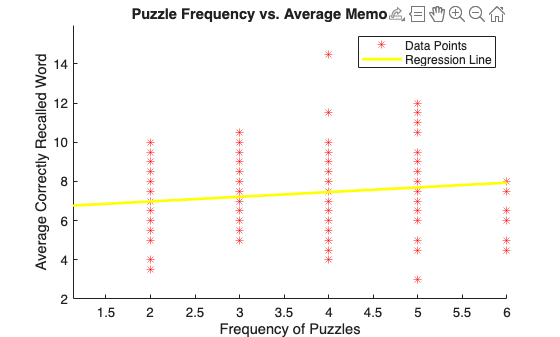

plot (FreqPuzzles,Puzzles_Fit, 'y-', LineWidth = 2)
xlabel('Frequency of Puzzles')
ylabel('Average Correctly Recalled Word')
legend('Data Points','Regression Line')

hold off


model_Puzzel = fitlm (data,'FreqPuzzles ~ CorrectRecalledNumAvg')

model_Puzzel = Linear regression model:
    FreqPuzzles ~ 1 + CorrectRecalledNumAvg

Estimated Coefficients:
                             Estimate       SE       tStat       pValue  
                             ________    ________    ______    __________

    (Intercept)               2.5844      0.38784    6.6637    2.4161e-10
    CorrectRecalledNumAvg    0.13147     0.050918    2.5819      0.010523


Number of observations: 207, Error degrees of freedom: 205
Root Mean Squared Error: 1.46
R-squared: 0.0315,  Adjusted R-Squared: 0.0268
F-statistic vs. constant model: 6.67, p-value = 0.0105

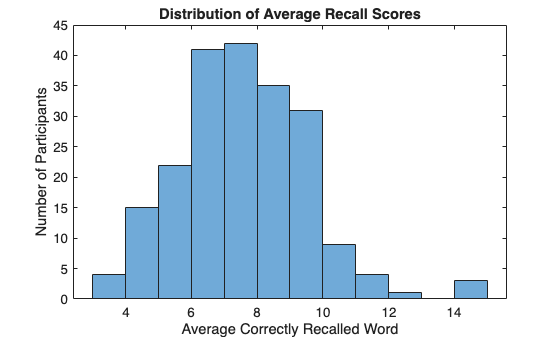


% Histogram of Correct Recalled Words Performed on the Memory Test
histogram(data.CorrectRecalledNumAvg)
title('Distribution of Average Recall Scores')
xlabel('Average Correctly Recalled Word')
ylabel('Number of Participants')


mean(data.CorrectRecalledNumAvg)

ans = 7.3502

std(data.CorrectRecalledNumAvg)

ans = 2.0023

min(data.CorrectRecalledNumAvg)

ans = 3

max(data.CorrectRecalledNumAvg)

ans = 15

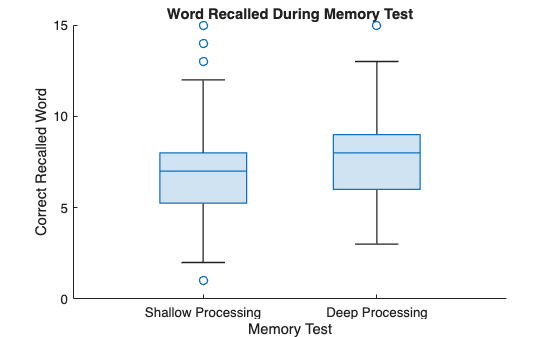


% Creating a boxplot comparing the scores on the memory test under shallow
% processing and deep processing conditions

boxchart([data.CorrectRecalledNumShallow,...
          data.CorrectRecalledNumDeep])
title('Word Recalled During Memory Test')
xlabel('Memory Test')
xticklabels({'Shallow Processing', 'Deep Processing'})
ylabel('Correct Recalled Word')

% Initially we looked at the question: do participants who played puzzles frequently in their 
% childhood have a better recall performance?

% Now we would like to analyses if other childhood expereieces have a positive correlation with 
% memory performance. 

% To understand this we would create a martix and perform a correlation matrix with different 
% childhood variable and its correlation with the average number of words recalled on the memory test.

matrix_1 = data(:,{'FreqPuzzles','FreqVideoGames','FreqReadForFun', ...
    'FreqArtWorkFun','FreqExercise','FreqMusicalInstrument', ...
    'FreqListentoMusic','FreqListentoMusicwithHomework', ...
    'FreqSpendTimeOutdoor','CorrectRecalledNumAvg'})

matrix_1 = 207×10 table
    FreqPuzzles    FreqVideoGames    FreqReadForFun    FreqArtWorkFun    FreqExercise    FreqMusicalInstrument    FreqListentoMusic    FreqListentoMusicwithHomework    FreqSpendTimeOutdoor    CorrectRecalledNumAvg
    ___________    ______________    ______________    ______________    ____________    _____________________    _________________    _____________________________    ____________________    _____________________

         2               4                 2                 1                6                    2                      1                          1                           4                         7   

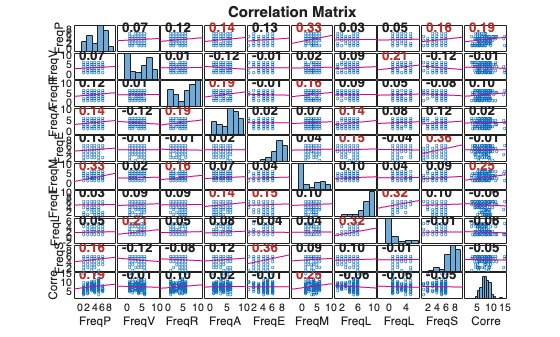


corrplot(matrix_1, 'Type', 'Spearman', 'TestR', 'on', 'Alpha', 0.05);


% In addition to the frequency of puzzle played in the childhood, activity
% such as the frequency they read for fun, frequency they played musical
% instrument also show a positive correlation with average number of worded
% recalled on memeory test.

% Create another matrix with these three variable and further look for
% correlation with word recalled under Shallow Processing and Deep
% Processing Memory test

matrix_2 = data (:, {'FreqPuzzles','FreqReadForFun','FreqMusicalInstrument', ...
    'CorrectRecalledNumAvg','CorrectRecalledNumDeep','CorrectRecalledNumShallow'})

matrix_2 = 207×6 table
    FreqPuzzles    FreqReadForFun    FreqMusicalInstrument    CorrectRecalledNumAvg    CorrectRecalledNumDeep    CorrectRecalledNumShallow
    ___________    ______________    _____________________    _____________________    ______________________    _________________________

         2               2                     2                         7                        7                          7            
         4               6                     2                         7                        7                          7            
         4               2                     1                       5.5                        6                          5            
         4               4                     1                       6.5   

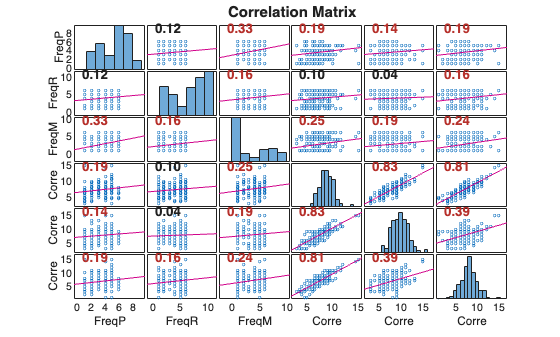


corrplot(matrix_2, 'Type', 'Spearman', 'TestR', 'on', 'Alpha', 0.05); 


% We noitce a stronger r corelation of there chidlhood experience variable and number 
% of word recalled under deep processing

#### Correlation Plot for Different Childhood Activity and Memory Performance

% 1 - Frequency of Musical Instrument vs Memory Test

% Building a scatterplot of frequency of musical intrument played in childhood and
% average number of words recalled on the memory test

scatter(data.FreqMusicalInstrument,CorrectRecalledNumAvg,'b*')
title('Musical Instrument Frequency vs. Average Memory Recall')

% Calculating correlation and fitting the model

hold on

coeff_MusicalInstrument = polyfit(data.FreqMusicalInstrument, CorrectRecalledNumAvg, 1)

coeff_MusicalInstrument =     0.2314    6.7299


MusicalInstrument_Fit = polyval(coeff_MusicalInstrument, data.FreqMusicalInstrument)

MusicalInstrument_Fit =     7.1926
    7.1926
    6.9613
    6.9613
    7.4240
    7.1926
    7.6554
    6.9613
    6.9613
    6.9613
    7.4240
    8.1181
    7.4240
    6.9613
    7.6554


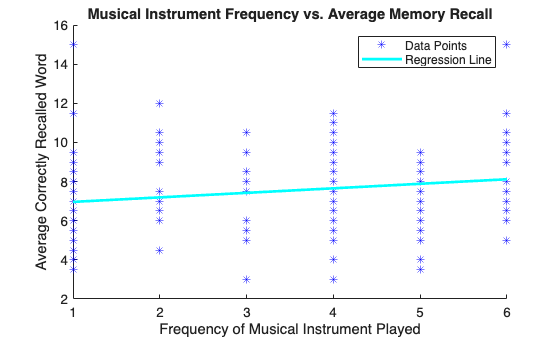


plot (data.FreqMusicalInstrument,MusicalInstrument_Fit, 'c-', LineWidth = 2)
xlabel('Frequency of Musical Instrument Played')
ylabel('Average Correctly Recalled Word')
legend('Data Points','Regression Line')

hold off


model_MusicalInstrument = fitlm (data,'FreqMusicalInstrument ~ CorrectRecalledNumAvg')

model_MusicalInstrument = Linear regression model:
    FreqMusicalInstrument ~ 1 + CorrectRecalledNumAvg

Estimated Coefficients:
                             Estimate       SE       tStat      pValue  
                             ________    ________    ______    _________

    (Intercept)                1.176      0.48848    2.4075      0.01695
    CorrectRecalledNumAvg    0.20478     0.064132     3.193    0.0016297


Number of observations: 207, Error degrees of freedom: 205
Root Mean Squared Error: 1.84
R-squared: 0.0474,  Adjusted R-Squared: 0.0427
F-statistic vs. constant model: 10.2, p-value = 0.00163



% 2 - Frequency of Reading for Fun in vs Memory Test

% Building another scatterplot of frequency of fun reading and average number of words recalled on the memory test
scatter(data.FreqReadForFun,CorrectRecalledNumAvg,'b*')
title('Read for Fun Frequency vs. Average Memory Recall')

% Calculating correlation and fitting the model

hold on

coeff_ReadforFun = polyfit(data.FreqReadForFun, CorrectRecalledNumAvg, 1)

coeff_ReadforFun =     0.1434    6.7868


ReadforFun_Fit = polyval(coeff_ReadforFun, data.FreqReadForFun)

ReadforFun_Fit =     7.0737
    7.6475
    7.0737
    7.3606
    7.5041
    7.3606
    7.3606
    7.0737
    7.2172
    6.9303
    7.5041
    7.0737
    7.6475
    6.9303
    7.0737


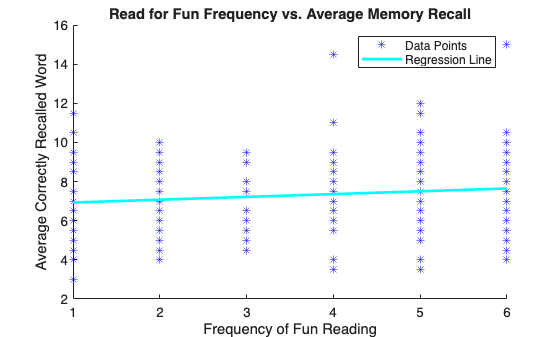

plot (data.FreqReadForFun,ReadforFun_Fit, 'c-', LineWidth = 2)
xlabel('Frequency of Fun Reading')
ylabel('Average Correctly Recalled Word')
legend('Data Points','Regression Line')

hold off


model_ReadforFun = fitlm (data,'FreqReadForFun ~ CorrectRecalledNumAvg')

model_ReadforFun = Linear regression model:
    FreqReadForFun ~ 1 + CorrectRecalledNumAvg

Estimated Coefficients:
                             Estimate       SE       tStat      pValue  
                             ________    ________    ______    _________

    (Intercept)               3.0442      0.48272    6.3063    1.726e-09
    CorrectRecalledNumAvg    0.12018     0.063375    1.8964     0.059318


Number of observations: 207, Error degrees of freedom: 205
Root Mean Squared Error: 1.82
R-squared: 0.0172,  Adjusted R-Squared: 0.0124
F-statistic vs. constant model: 3.6, p-value = 0.0593

#### Building Predictive Model

% Using three predictive molde: multiple linear regression, regression tree
% and random forest models to analyse model prection of memeory score from
% childhood memories

predictor = data(:,{'FreqPuzzles','FreqReadForFun','FreqMusicalInstrument'});
response = data.CorrectRecalledNumAvg

response =     7.0000
    7.0000
    5.5000
    6.5000
    9.5000
    9.5000
    9.0000
    9.5000
    5.5000
    5.5000
    8.5000
    7.0000
    9.5000
    7.5000
    8.5000



rng(123)

cv = cvpartition(height(data),'HoldOut',0.2);

trainIdx = training(cv);
testIdx = test(cv);

predictor_train = predictor(trainIdx,:);
predictor_test = predictor(testIdx,:);
response_train = response(trainIdx);
response_test = response(testIdx);

% Model 1 - Multiple Linear Regression
lm_model = fitlm(predictor_train, response_train);
Pred_lm = predict (lm_model, predictor_test);
rmse_lm = sqrt(mean((response_test - Pred_lm).^2));
SSres_lm = sum ((response_test - Pred_lm).^2);
SStot_lm = sum ((response_test- mean(response_test)).^2);
R2_lm = 1 - (SSres_lm/SStot_lm)

R2_lm = 0.0485

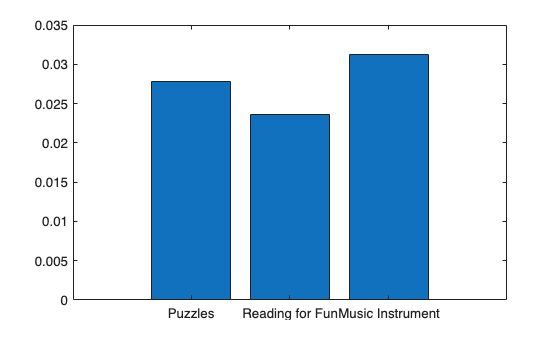


% Model 2 - Regression Tree
rtree_model = fitrtree(predictor_train, response_train);
Pred_rtree = predict(rtree_model, predictor_test);
rmse_rtree = sqrt(mean((response_test-Pred_rtree).^2));
SSres_rtree = sum((response_test-Pred_rtree).^2);
SStot_rtree = sum((response_test-mean(response_test)).^2);
R2_rtree = 1 - SSres_rtree/SStot_rtree;

% Model 3 - Random Forest
rf_model = fitrensemble(predictor_train,response_train,...
                       'Method','Bag',...
                       'NumLearningCycles',207);
Pred_rf = predict(rf_model,predictor_test);
rmse_rf = sqrt(mean((response_test-Pred_rf).^2));
SSres_rf = sum((response_test-Pred_rf).^2);
SStot_rf = sum((response_test-mean(response_test)).^2);
R2_rf = 1 - SSres_rf/SStot_rf;

importance = predictorImportance(rf_model);
bar(importance)
xticklabels({'Puzzles','Reading for Fun','Music Instrument'})


% Comparing Models
results = table(...
    ["Multiple Linear Regression";"Regression Tree";"Random Forest"],...
    [rmse_lm;rmse_rtree;rmse_rf],...
    [R2_lm;R2_rtree;R2_rf],...
    'VariableNames',{'Model','RMSE','R2'});
disp(results)

               Model                 RMSE         R2    
    ____________________________    ______    __________

    "Multiple Linear Regression"    1.7769      0.048494
    "Regression Tree"               1.9069     -0.095855
    "Random Forest"                 1.8272    -0.0061017

